Compare runtimes for problems which were solved in general robotics toolbox (grt)

% runtimes_sp1 = run_timing_test(@subproblem_setups.sp_1.setup, {@subproblem_setups.sp_1.run, @subproblem_setups.sp_1.run_grt}, 100, 10)
runtimes_sp1 = run_timing_test(@subproblem_setups.sp_1.setup, {@subproblem_setups.sp_1.run, @subproblem_setups.sp_1.run_mex}, 100, 150)

    0.2000

    0.4000

    0.6000

    0.8000



runtimes_sp1 = 1.0e-04 *

    0.0577    0.2582
    0.0568    0.2407
    0.0564    0.2222
    0.0574    0.2190
    0.0552    0.2229
    0.0554    0.2412
    0.0551    0.2553
    0.0569    0.2258
    0.0554    0.2301
    0.0569    0.2235


[rt_filt_sp1_linear, rt_filt_sp1_mex] = compare_runs(runtimes_sp1)

ans = 5.9933e-06

ans = 2.3325e-05

rt_filt_sp1_linear = 1.0e-05 *

    0.5774
    0.5675
    0.5637
    0.5744
    0.5519
    0.5537
    0.5515
    0.5686
    0.5538
    0.5687


rt_filt_sp1_mex = 1.0e-04 *

    0.2582
    0.2407
    0.2222
    0.2190
    0.2229
    0.2412
    0.2553
    0.2258
    0.2301
    0.2235


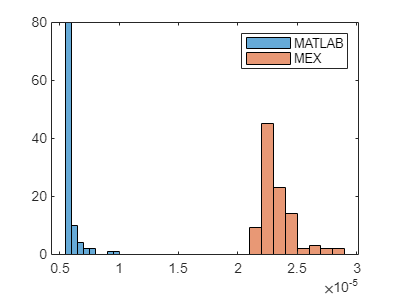

legend("MATLAB", "MEX")

runtimes_sp2 = run_timing_test(@subproblem_setups.sp_2.setup, {@subproblem_setups.sp_2.run, @subproblem_setups.sp_2.run_grt}, 100, 10)

    0.2000

    0.4000

    0.6000

    0.8000



runtimes_sp2 = 1.0e-04 *

    0.2377    0.2836
    0.2096    0.2642
    0.2268    0.2644
    0.2609    0.2571
    0.2512    0.2603
    0.2073    0.2570
    0.2095    0.2697
    0.2143    0.2638
    0.2077    0.2624
    0.2079    0.2612


ans = 2.1902e-05

ans = 2.6200e-05

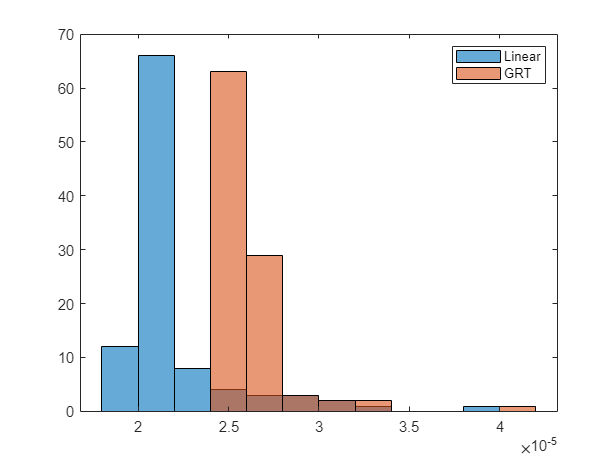

[rt_filt_sp2_linear, rt_filt_sp2_grt] = compare_runs(runtimes_sp2);

runtimes_sp3 = run_timing_test(@subproblem_setups.sp_3.setup, {@subproblem_setups.sp_3.run, @subproblem_setups.sp_3.run_grt}, 100, 10)

    0.2000

    0.4000

    0.6000

    0.8000



runtimes_sp3 = 1.0e-04 *

    0.1019    0.1563
    0.0977    0.1453
    0.0962    0.0873
    0.0947    0.0969
    0.0949    0.0757
    0.0942    0.0659
    0.0945    0.0678
    0.0937    0.0557
    0.1289    0.0558
    0.1397    0.0563


ans = 1.0759e-05

ans = 5.9353e-06

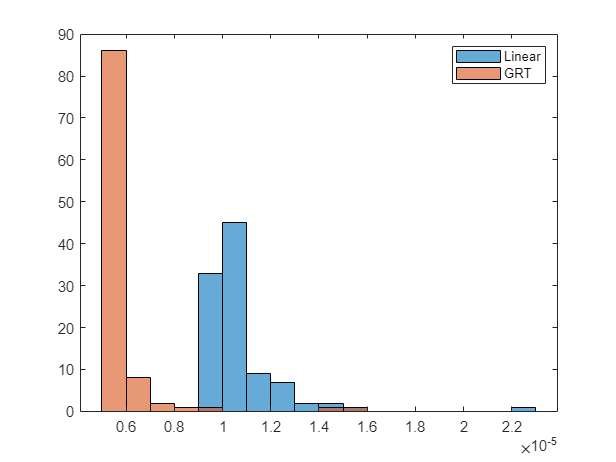

[rt_filt_sp3_linear, rt_filt_sp3_grt] = compare_runs(runtimes_sp3);

runtimes_sp4 = run_timing_test(@subproblem_setups.sp_4.setup, {@subproblem_setups.sp_4.run, @subproblem_setups.sp_4.run_grt}, 100, 10)

    0.2000

    0.4000

    0.6000

    0.8000



runtimes_sp4 = 1.0e-04 *

    0.1067    0.1088
    0.0954    0.0972
    0.0951    0.0957
    0.0950    0.1036
    0.0959    0.0969
    0.1001    0.0946
    0.0948    0.0975
    0.0933    0.0971
    0.0940    0.0952
    0.0935    0.0971


ans = 1.0163e-05

ans = 1.0104e-05

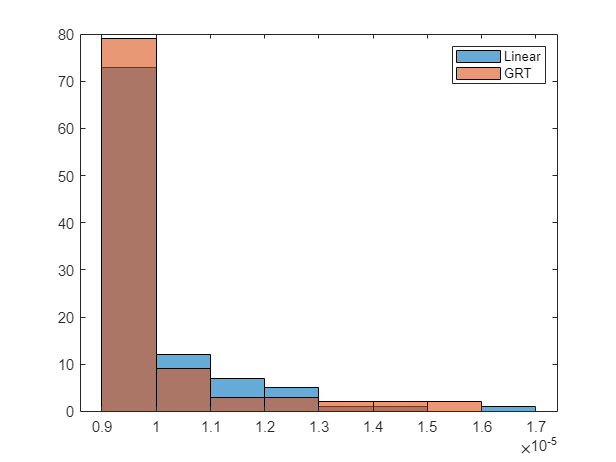

[rt_filt_sp4_linear, rt_filt_sp4_grt] = compare_runs(runtimes_sp4);

Runtimes for problems unique to this repo

runtimes_sp2_extended = run_timing_test(@subproblem_setups.sp_2E.setup, {@subproblem_setups.sp_2E.run, @subproblem_setups.sp_2E.run_mex}, 100, 10);

    0.2000

    0.4000

    0.6000

    0.8000



[rt_filt_sp2E, rt_filt_sp2E_mex] = compare_runs(runtimes_sp2_extended);

ans = 2.7769e-05

ans = 2.8709e-05

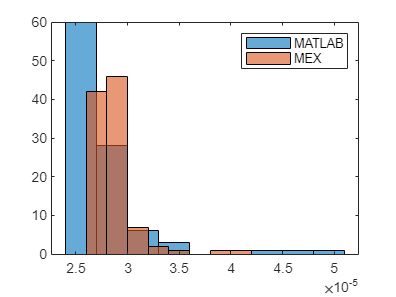

legend("MATLAB", "MEX")

runtimes_sp5 = run_timing_test(@subproblem_setups.sp_5.setup, {@subproblem_setups.sp_5.run, @subproblem_setups.sp_5.run_mex}, 100, 10);

    0.2000

    0.4000

    0.6000

    0.8000



[rt_filt_sp5, rt_filt_sp5_mex] = compare_runs(runtimes_sp5);

ans = 9.0587e-05

ans = 4.8608e-05

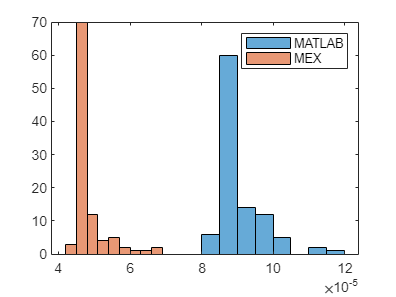

legend("MATLAB", "MEX")

runtimes_sp6 = run_timing_test(@subproblem_setups.sp_6.setup, {@subproblem_setups.sp_6.run, @subproblem_setups.sp_6.run_mex}, 100, 20);

    0.2000

    0.4000

    0.6000

    0.8000



%rt_filt_sp6 = plot_single_run(runtimes_sp6);
[rt_filt_sp6, rt_filt_sp6_mex] = compare_runs(runtimes_sp6);

ans = 1.2030e-04

ans = 5.1785e-05

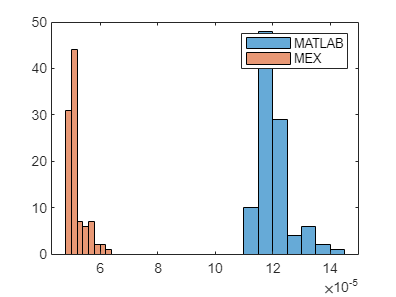

legend("MATLAB", "MEX")

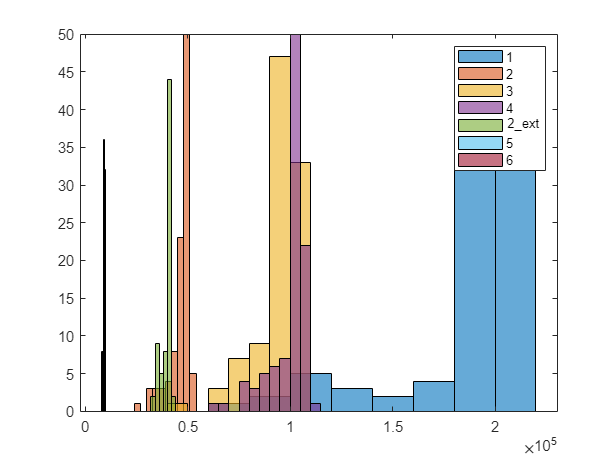

histogram(1./rt_filt_sp1_linear); hold on
histogram(1./rt_filt_sp2_linear);
histogram(1./rt_filt_sp3_linear);
histogram(1./rt_filt_sp4_linear);
histogram(1./rt_filt_sp2_ext);
histogram(1./rt_filt_sp5);
histogram(1./rt_filt_sp6); hold off
legend(["1", "2","3","4","2\_ext","5","6"])

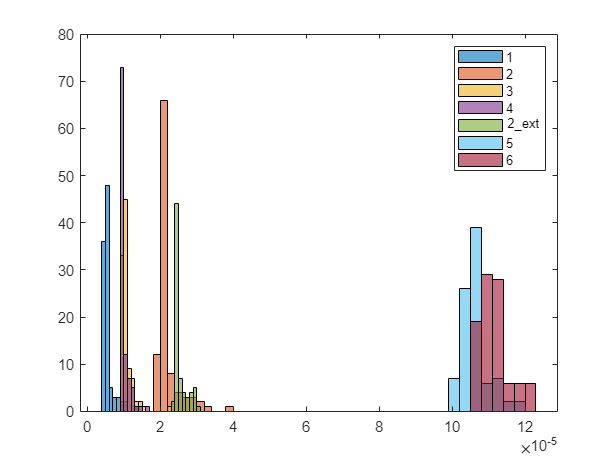


histogram(rt_filt_sp1_linear); hold on
histogram(rt_filt_sp2_linear);
histogram(rt_filt_sp3_linear);
histogram(rt_filt_sp4_linear);
histogram(rt_filt_sp2_ext);
histogram(rt_filt_sp5);
histogram(rt_filt_sp6); hold off
legend(["1", "2","3","4","2\_ext","5","6"])

function [runtimes_linear, runtimes_grt] = compare_runs(runtimes)
    runtimes_linear = runtimes(:,1);
    runtimes_grt = runtimes(:,2);
    %runtimes_linear = rmoutliers(runtimes(:,1));
    %runtimes_grt = rmoutliers(runtimes(:,2));
    
    mean(runtimes_linear)
    mean(runtimes_grt)
    
    histogram(runtimes_linear); hold on
    histogram(runtimes_grt); hold off
    legend("Linear", "GRT")
end

function  runtimes= plot_single_run(runtimes)
    runtimes = rmoutliers(runtimes(:,1));
    mean(runtimes)
    histogram(runtimes);
end